# Starter code (2-class classifier: cats vs. dogs)

Prof. Oge Marques, PhD - (C) 2020-2022

% Inspired by the example "Deep Learning for Pet Classification" 
% (Copyright 2016 The MathWorks, Inc.)

## Part 1: Load and inspect Pre-trained Convolutional Neural Network (CNN)

## 1.1: Loading a pre-trained "AlexNet"

% Ensure that you have downloaded and installed the 
% "Deep Learning Toolbox Model for AlexNet Network" support package. 

% See https://www.mathworks.com/matlabcentral/fileexchange/59133-deep-learning-toolbox-model-for-alexnet-network
% and
% https://www.mathworks.com/help/deeplearning/ug/pretrained-convolutional-neural-networks.html
% for additional information.

model1 = alexnet;

## 1.2: Inspect the CNN's layers

model1.Layers

ans =   25×1 Layer array with layers:

     1   'data'     Image Input                   227×227×3 images with 'zerocenter' normalization
     2   'conv1'    2-D Convolution               96 11×11×3 convolutions with stride [4  4] and padding [0  0  0  0]
     3   'relu1'    ReLU                          ReLU
     4   'norm1'    Cross Channel Normalization   cross channel normalization with 5 channels per element
     5   'pool1'    2-D Max Pooling               3×3 max pooling with stride [2  2] and padding [0  0  0  0]
     6   'conv2'    2-D Grouped Convolution       2 groups of 128 5×5×48 convolutions with stride [1  1] and padding [2  2  2  2]
     7   'relu2'    ReLU                          ReLU
     8   'norm2'    Cross Channel Normalization   cross channel normalization with 5 channels per element
     9   'pool2'    2-D Max Pooling               3×3 max pooling with stride [2  2] and padding [0  0  0


% The intermediate layers make up the bulk of the CNN. These are a series
% of convolutional layers, interspersed with rectified linear units (ReLU)
% and max-pooling layers [2]. Following the these layers are 3
% fully-connected layers.

% The final layer is the classification layer and its properties depend on
% the classification task. In this example, the CNN model that was loaded
% was trained to solve a 1000-way classification problem. Thus the
% classification layer has 1000 classes from the ImageNet dataset. 

% Inspect the last layer
model1.Layers(end)

ans =   ClassificationOutputLayer with properties:

            Name: 'output'
         Classes: [1000×1 categorical]
    ClassWeights: 'none'
      OutputSize: 1000

   Hyperparameters
    LossFunction: 'crossentropyex'



% Number of class names for ImageNet classification task
numel(model1.Layers(end).ClassNames)

ans = 1000


% Note that the CNN model is not going to be used for the original
% classification task. It is going to be re-purposed to solve a different
% classification task on the pets dataset.

## Part 2: Set up image data

## 2.1: Load simplified dataset and build image store

dataFolder = './data/PetImages';
categories = {'cat', 'dog'};
imds = imageDatastore(fullfile(dataFolder, categories), 'LabelSource', 'foldernames');
tbl = countEachLabel(imds);
disp (tbl)

    Label    Count
    _____    _____

     cat      20  
     dog      20  




% Use the smallest overlap set
% (useful when the two classes have different number of elements but not
% needed in this case)
minSetCount = min(tbl{:,2});

% Use splitEachLabel method to trim the set.
imds = splitEachLabel(imds, minSetCount, 'randomize');

% Notice that each set now has exactly the same number of images.
countEachLabel(imds)

ans = 2×2 table
    Label    Count
    _____    _____

     cat      20  
     dog      20  


## 2.2: Pre-process Images For CNN

AlexNet can only process RGB images that are 227-by-227. To avoid re-saving all the images to this format, setup the `imds` read function, `imds.ReadFcn`, to pre-process images on-the-fly. The `imds.ReadFcn` is called every time an image is read from the `ImageDatastore`.

Set the ImageDatastore ReadFcn

imds.ReadFcn = @(filename)readAndPreprocessImage(filename);

## 2.3: Divide data into training and validation sets

[trainingSet, validationSet] = splitEachLabel(imds, 0.5, 'randomized');

countEachLabel(trainingSet)

ans = 2×2 table
    Label    Count
    _____    _____

     cat      10  
     dog      10  


countEachLabel(validationSet)

ans = 2×2 table
    Label    Count
    _____    _____

     cat      10  
     dog      10  


## Part 3: Transfer Learning

% The convolutional layers of the network extract image features that the 
% last learnable layer and the final classification layer use to classify 
% the input image. 

% To retrain a pretrained network to classify new images, we must replace these 
% last layers with new layers adapted to the new data set.

## 3.1: Freeze all but last three layers

layersTransfer = model1.Layers(1:end-3);
numClasses = 2; % cat and dog

layers = [
    layersTransfer
    fullyConnectedLayer(numClasses,'WeightLearnRateFactor',20,'BiasLearnRateFactor',20)
    softmaxLayer
    classificationLayer];

## 3.2: Configure training options

options = trainingOptions('adam', ...
    'MiniBatchSize',32, ...
    'MaxEpochs',30, ...
    'InitialLearnRate',5e-4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',validationSet, ...
    'ValidationFrequency',5, ...
    'Verbose',false, ...
    'Plots','training-progress', ...
    'L2Regularization',1e-4, ...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropFactor',0.5, ...
    'LearnRateDropPeriod',5);


## 3.3: Retrain network

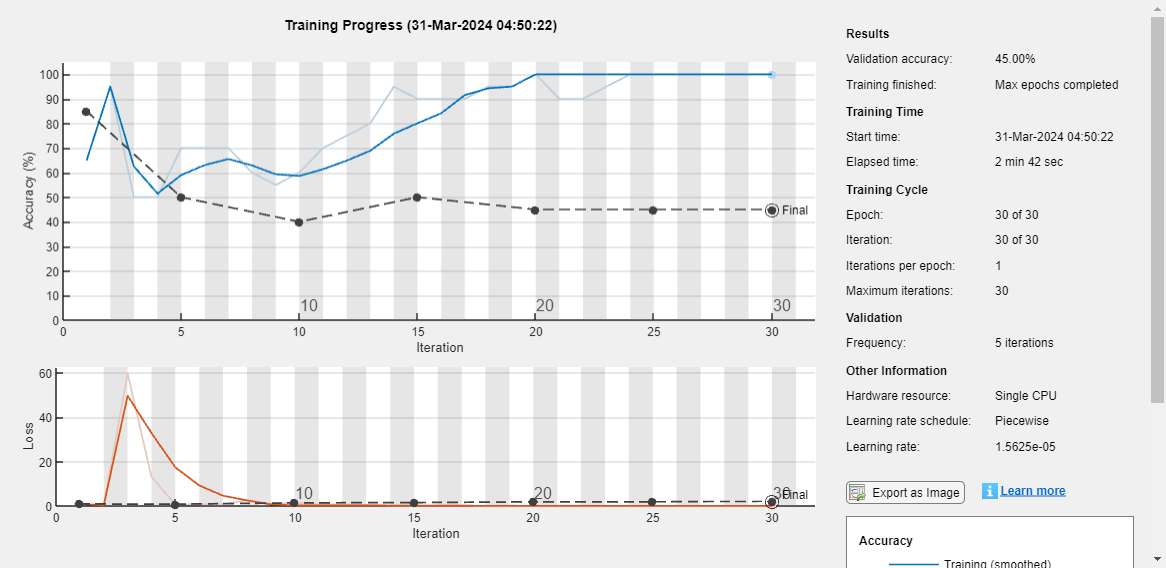

model2 = trainNetwork(trainingSet,layers,options);


% modelTransfer = trainNetwork(trainingSet, layerGraph(model),options); % for squeezenet

## 3.4: Classify the validation images using the fine-tuned network.

[YPred,scores] = classify(model2,validationSet);

matrix:

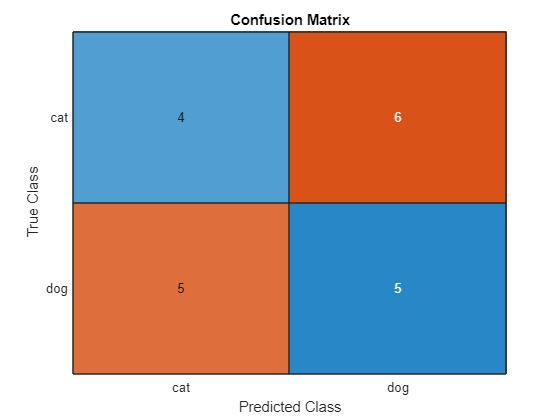


YPredCategorical = categorical(YPred);

% Ensure this line is present to get the actual labels from the validation set
YValidation = validationSet.Labels;

% Convert the actual labels to categorical for consistency with predicted labels
YValidationCategorical = categorical(YValidation);

% Calculate the confusion matrix using the categorical arrays
% This matrix compares the actual labels against the predicted labels
confMat = confusionmat(YValidationCategorical, YPredCategorical);

% Plotting the confusion matrix
% Provides a visual representation of the model's performance
% 'categories' should contain your class names for accurate labeling
figure;
confusionchart(confMat, categories);
title('Confusion Matrix');

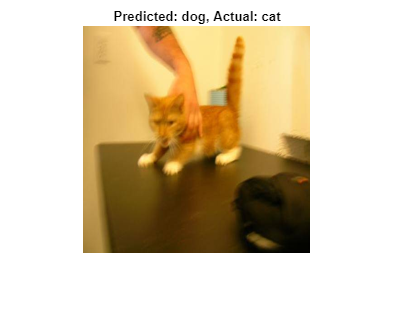

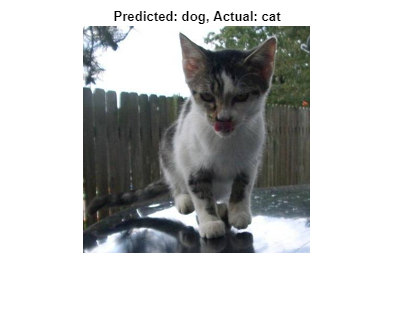

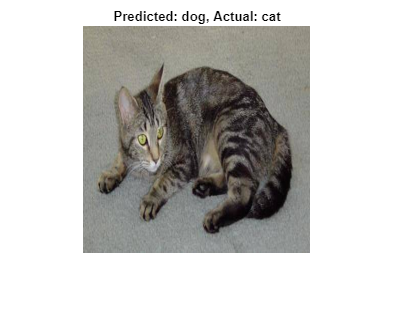

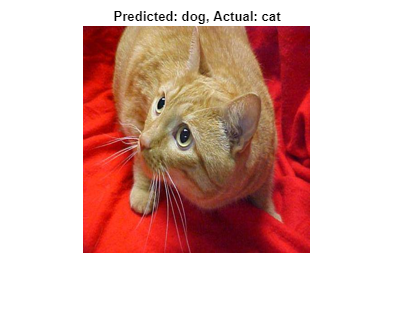

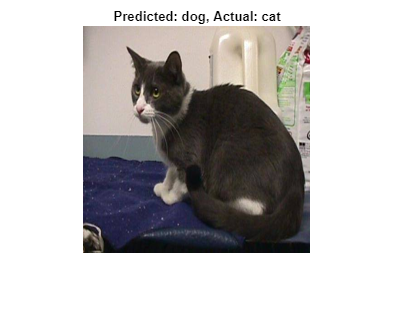

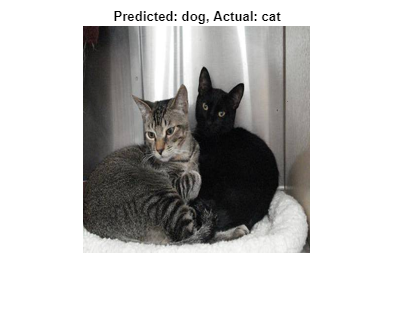

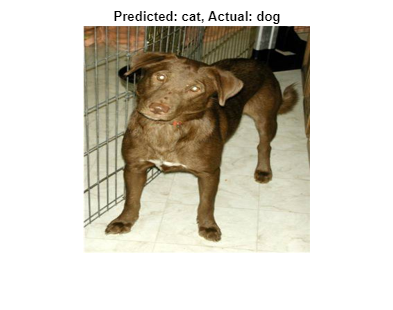

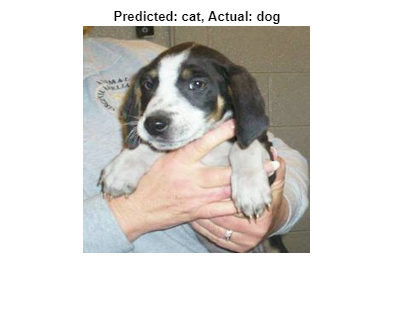

%incorrect classification
% Assuming YPred and YValidation contain the predictions and actual labels, respectively

% Find indices where predictions do not match the actual labels
incorrectIndices = find(YPred ~= YValidation);

% Limit the number of incorrect samples to inspect to a maximum of 10
numIncorrectToInspect = min(10, numel(incorrectIndices));

% Loop over the determined number of incorrect samples
for i = 1:numIncorrectToInspect
    % Get the index of the current incorrect classification
    idx = incorrectIndices(i);

    % Read the image corresponding to the incorrect classification
    % Note: Adjust the data source (e.g., validationSet or augimdsValidation) as needed
    img = readimage(validationSet, idx);

    % Retrieve the predicted and actual labels for the current incorrect sample
    predictedLabel = YPred(idx);
    actualLabel = YValidation(idx);

    % Display the incorrectly classified image with a title indicating the predicted and actual labels
    figure;
    imshow(img);
    title(sprintf('Predicted: %s, Actual: %s', string(predictedLabel), string(actualLabel)));
end

## 3.5: Calculate the classification accuracy on the validation set.

Accuracy is the fraction of labels that the network predicts correctly.

YValidation = validationSet.Labels;
accuracy = mean(YPred == YValidation);
fprintf("The validation accuracy is: %.2f %%\n", accuracy * 100);

The validation accuracy is: 45.00 %


## 3.6: Test it on unseen images

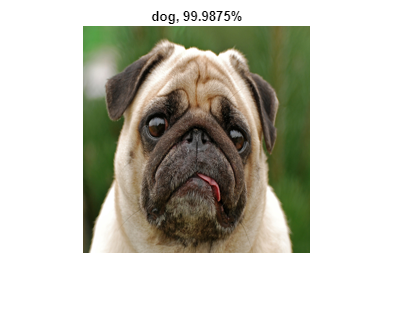

newImage1 = './dog.jpg'; % any dog image should do!
img1 = readAndPreprocessImage(newImage1);
YPred1 = predict(model2,img1);
[confidence1,idx1] = max(YPred1);
label1 = categories{idx1};
% Display test image and assigned label
figure
imshow(img1)
title(string(label1) + ", " + num2str(100*confidence1) + "%");

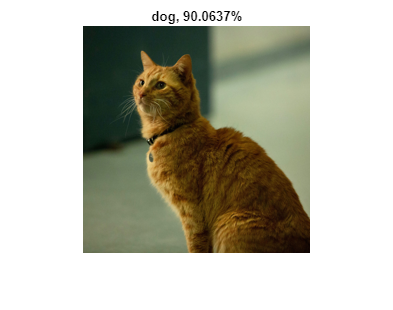


newImage2 = './cat.jpg'; % any cat image should do!
img2 = readAndPreprocessImage(newImage2);
YPred2 = predict(model2,img2);
[confidence2,idx2] = max(YPred2);
label2 = categories{idx2};
% Display test image and assigned label
figure
imshow(img2)
title(string(label2) + ", " + num2str(100*confidence2) + "%");

## 3.7: Test it on unseen images: Your turn!

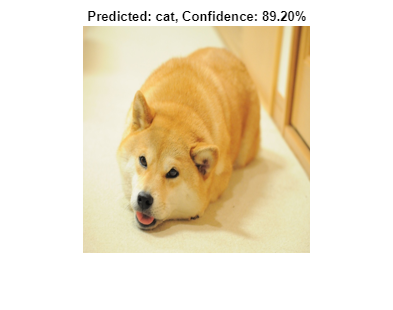

% What about the iconic "Doge"?
% ENTER YOUR CODE HERE
% ..
% ..
% ..
% Define the path to the Doge image
dogeImagePath = './doge.jpg';

% Read and preprocess the Doge image according to the model's requirements
dogeImage = readAndPreprocessImage(dogeImagePath);

% Classify the preprocessed Doge image using the fine-tuned model 'model2'
% and obtain the predicted label along with the classification scores
[YPredDoge, scoresDoge] = classify(model2, dogeImage);

% Calculate the confidence of the prediction as the maximum score
confidenceDoge = 100 * max(scoresDoge);

% Display the Doge image along with the predicted label and its confidence
figure;
imshow(dogeImage);
title(sprintf('Predicted: %s, Confidence: %.2f%%', string(YPredDoge), confidenceDoge));

## Part 4: Data augmentation

% Data augmentation helps prevent the network from overfitting and
% memorizing the exact details of the training images.

% In MATLAB, this can be done using the "Augmented Image Datastore"
% (https://www.mathworks.com/help/deeplearning/ref/augmentedimagedatastore.html)

% Despite its name, however, it DOES NOT increase the actual number of
% samples. When you use an augmented image datastore as a source of
% training images, the datastore randomly perturbs the training data for
% each epoch, so that each epoch uses a slightly different data set. The
% actual number of training images at each epoch does not change. The
% transformed images are not stored in memory.

## 4.1: Defining the imageAugmenter object

In our case, we shall use an augmented image datastore to randomly flip the training images along the vertical axis and randomly translate them up to 30 pixels and scale them up to 10% horizontally and vertically.

pixelRange = [-30 30];
scaleRange = [0.9 1.1];
imageAugmenter = imageDataAugmenter( ...
    'RandXReflection',true, ...
    'RandXTranslation',pixelRange, ...
    'RandYTranslation',pixelRange, ...
    'RandXScale',scaleRange, ...
    'RandYScale',scaleRange);

## 4.2: Building the augmented training and validation sets

inputSize = model1.Layers(1).InputSize;
augimdsTrain = augmentedImageDatastore(inputSize(1:2),trainingSet, ...
    'DataAugmentation',imageAugmenter);

disp(augimdsTrain.NumObservations) % You should see 28

    20




augimdsValidation = augmentedImageDatastore(inputSize(1:2),validationSet);

disp(augimdsValidation.NumObservations) % You should see 12

    20



## 4.3: Train the network with augmented datasets

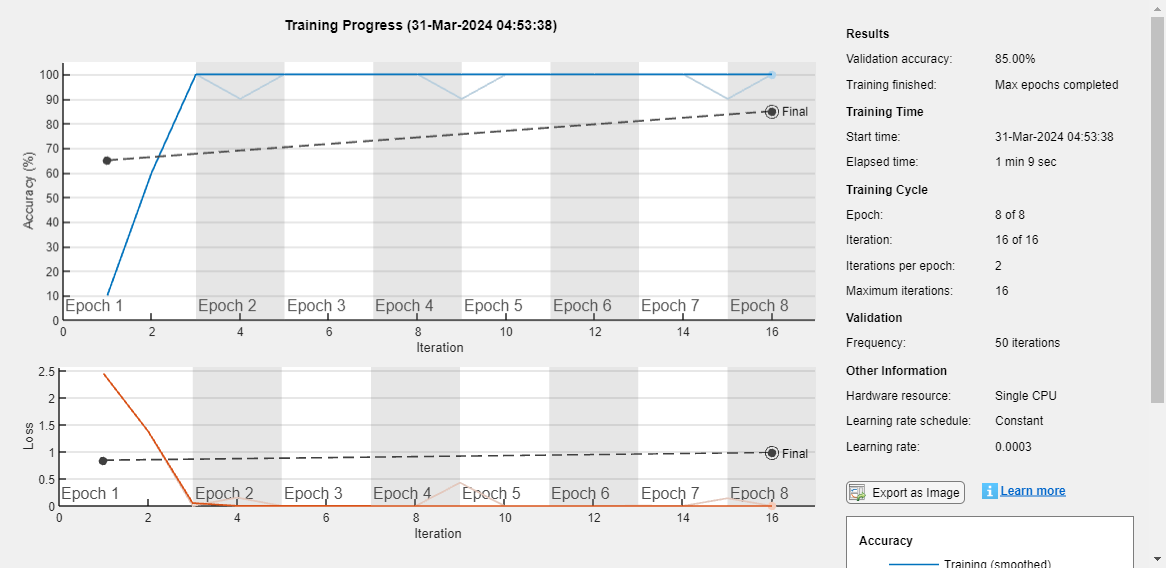

miniBatchSize = 10;
options = trainingOptions('sgdm', ...
    'MiniBatchSize',miniBatchSize, ...
    'MaxEpochs',8, ...
    'InitialLearnRate',3e-4, ...
    'ValidationData',augimdsValidation, ...
    'Verbose',false, ...
    'Plots','training-progress');

model3 = trainNetwork(augimdsTrain,layers,options);

## 4.4: Classify the validation images using the fine-tuned network.

[YPredAug,probsAug] = classify(model3,augimdsValidation);

confusion matrix:

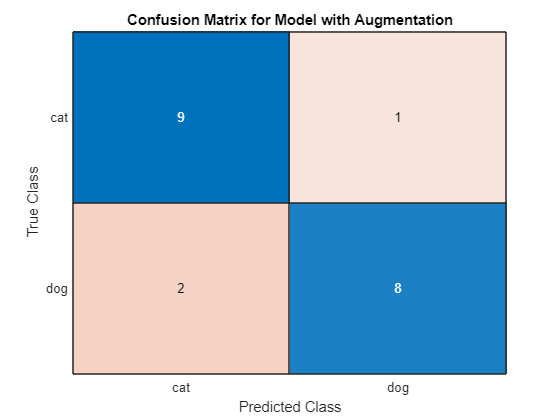

% Obtain predictions (YPredAug) and actual labels (YValidationAug) from the augmented validation set

% Calculate the confusion matrix using the predictions and actual labels
confMat3 = confusionmat(YValidationAug, YPredAug);

% Create a figure to display the confusion matrix chart
figure;

% Initialize and configure the confusion matrix chart with class categories for clarity
cmChart = confusionchart(confMat3, categories);

% Set the title of the confusion matrix chart
cmChart.Title = 'Confusion Matrix for Model with Augmentation';

## 4.5: Calculate the classification accuracy on the validation set.

Accuracy is the fraction of labels that the network predicts correctly.

YValidationAug = validationSet.Labels;
accuracyAug = mean(YPredAug == YValidationAug);
fprintf("The validation accuracy is: %.2f %%\n", accuracyAug * 100);

The validation accuracy is: 85.00 %


## Part 5: Larger datasets

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:23 |       71.88% |       42.86% |       0.7068 |       4.0787 |      1.0000e-04 |
|       1 |           5 |       00:00:59 |       34.38% |       57.14% |       0.7391 |       0.7236 |      1.0000e-04 |
|       2 |          10 |       00:01:44 |       56.25% |       60.71% |       0.6740 |       0.6588 |      1.0000e-04 |
|       3 |          15 |       00:02:28 |       56.25% |       43.75% |       0.6623 |   

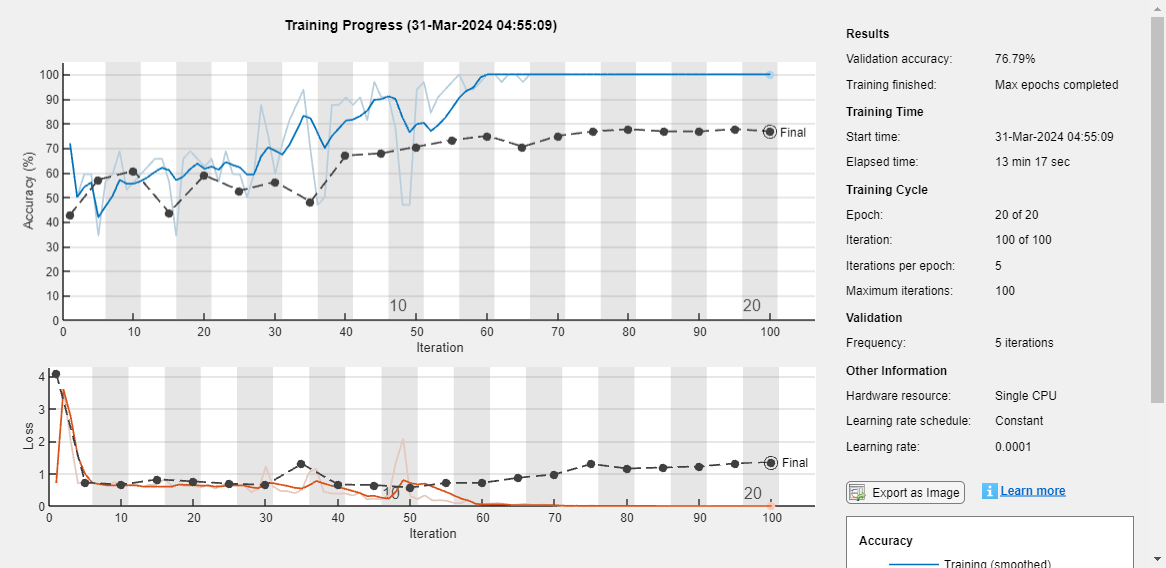

% In this part, you will use the Kaggle dataset and basically repeat the
% steps in Parts 2 and 3 (and 4, if you wish) using larger training and
% validation datasets.

% See Guidelines for instructions.

% ENTER YOUR CODE HERE
% ..
% ..
% ..
% Define the path to the larger dataset and specify the categories
% Define the directory containing the expanded dataset and the categories of interest
expandedDataDir = './data/largedatasetimages';
animalCategories = {'cat', 'dog'};

% Set up the datastore for the expanded dataset with a custom read function
expandedImds = imageDatastore(fullfile(expandedDataDir, animalCategories), 'LabelSource', 'foldernames');
expandedImds.ReadFcn = @(file) customPreprocessImage(file);

% Divide the expanded dataset into subsets for training and validation
[expandedTrainingImds, expandedValidationImds] = splitEachLabel(expandedImds, 0.6, 'randomize');

% Transfer learning setup: Use a pre-existing model's layers, excluding the last three
transferredLayers = model1.Layers(1:end-3);
totalCategories = numel(animalCategories);  % Set based on the number of categories

% Construct new layers for the updated model structure
updatedLayers = [
    transferredLayers;
    fullyConnectedLayer(totalCategories, 'WeightLearnRateFactor', 20, 'BiasLearnRateFactor', 20);
    softmaxLayer;
    classificationLayer];

% Training configurations for the expanded dataset
expandedOptions = trainingOptions('rmsprop', ...
    'MiniBatchSize', 32, ...
    'MaxEpochs', 20, ...
    'InitialLearnRate', 1e-4, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', expandedValidationImds, ...
    'ValidationFrequency', 5, ...
    'Verbose', true, ...
    'Plots', 'training-progress');

% Train the neural network with the newly configured layers and options
updatedModel = trainNetwork(expandedTrainingImds, updatedLayers, expandedOptions);


% Classify the validation set using the newly trained model
[predictedLabels, predictedScores] = classify(updatedModel, expandedValidationImds);

% Retrieve the actual labels from the validation set
actualLabels = expandedValidationImds.Labels;

% Calculate the model's accuracy on the validation set
modelAccuracy = mean(predictedLabels == actualLabels);
fprintf('Model accuracy on the expanded validation set: %.2f%%\n', modelAccuracy * 100);

Model accuracy on the expanded validation set: 76.79%


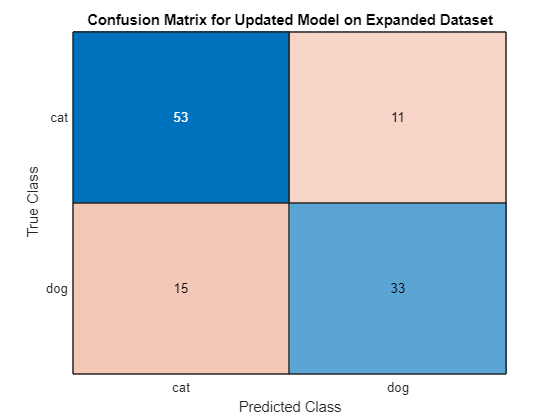


% Generate and display the confusion matrix
confusionMat = confusionmat(actualLabels, predictedLabels);
figure;
confusionChart = confusionchart(confusionMat, animalCategories);
confusionChart.Title = 'Confusion Matrix for Updated Model on Expanded Dataset';



% Classify the images in the larger validation set
[YPredLarge, scoresLarge] = classify(modelLarge, validationSetLarge);

% Calculate the accuracy on the larger validation set
YValidationLarge = validationSetLarge.Labels;
accuracyLarge = mean(YPredLarge == YValidationLarge);
fprintf("Validation accuracy with the larger dataset: %.2f%%\n", accuracyLarge * 100);

Validation accuracy with the larger dataset: 93.75%


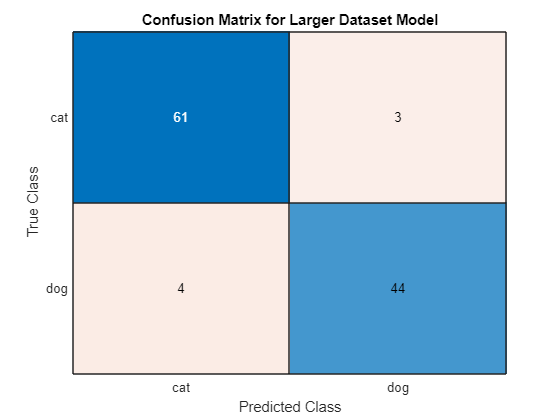


% Generate and display the confusion matrix for the larger dataset
confMatLarge = confusionmat(YValidationLarge, YPredLarge);
figure;
confusionchart(confMatLarge, categories);
title('Confusion Matrix for Larger Dataset Model');

Accuracy table